初版：2021年12月4日

# シミュレーション　講義ノート No.2

#### 藤原　哉

#### 農林中央金庫

## 1.定積分の計算

　定積分には確率的な要素が含まれていないためモンテカルロ・シミュレーションとは関係が無いように見えるが、定積分を確率的な表現に変形することでモンテカルロ・シミュレーションで評価するすることが出来る。なお、低次元（３次元程度）ではモンテカルロ・シミュレーションよりも効率的な数値計算手法があるので、実際に有用となるのは多次元の積分計算である。ここでは、考え方を理解するために１次元の問題を例として取り上げる。１次元の連続関数を $f(x)$として区間 $[xmin,xmax]$での定積分 $\int_{xmin}^{xmax} f(x) {\rm d}x$は以下のように $[xmin,xmax]$での一様分布に従う確率変数 $X \sim U([xmin,xmax])$ の期待値で表現できる。 $\frac{1}{xmax-xmin}$が $[xmin,xmax]$での一様分布の密度関数であることに注意する。


$$\int_{xmin}^{xmax} f(x) {\rm d} x = (xmax-xmin) \int_{xmin}^{xmax} f(x) \frac{ 1}{xmax-xmin} {\rm d} x \\ =   \mathbb{E}\left[(xmax-xmin) f(X) \right], \\ X \sim U\left([xmin,xmax] \right)$$


これより、$[xmin,xmax]$での一様分布に従う乱数列 $x_1,\cdots,x_N$ を生成し、 $\frac{1}{N} \sum_{i=1}^N (xmax-xmin) f(x_i)$を計算することで定積分$\int_{xmin}^{xmax} f(x) {\rm d}x$の数値解を得ることが出来る。

数値例として $\int_{-5}^5 x^2 {\rm d} x$を一様乱数によるモンテカルロ・シミュレーションで求める。乱数の数が10000として解析解と比較する。vAnalyticalが解析解、vMCがモンテカルロ・シミュレーションでの結果である。

clear;

xmin = -5; 
xmax = 5; 
% 解析解
f = @(x) x.^2 ; 
vAnalytical = integral(f,xmin,xmax);

% シミュレーション
Nsim = 10000; 
vfu = getMyRNG(xmin,xmax,'Uniform'); % [xmin,xmax]一様乱数を生成する関数の作成
xsu = vfu(Nsim,1);
vMC = mean(f(xsu))*(xmax-xmin); 

% 解析解とシミュレーションとの比較
rst1 = table(vAnalytical, vMC);
disp(rst1);

    vAnalytical     vMC  
    ___________    ______

      83.333       84.386



定積分をモンテカルロ・シミュレーションで評価する方法では、一様分布以外の分布を用いることも可能である。$f(x)$の関数形によっては、一様分布以外の分布を用いると計算が効率的になることもある。

例えば、切断正規分布( ${\rm TrN}(\mu,\sigma,[xmin,xmax])$ 平均 $\mu $, 標準偏差 $\sigma $)を用いてモンテカルロ・シミュレーションで評価することを考える。

切断正規分布の密度関数は、$N(x,\mu,\sigma) = \int_{-\infty}^{x} \frac{1}{\sqrt{2\pi} \sigma} {\rm e}^{-\frac{1}{2} \left(\frac{x-\mu}{\sigma} \right)^2} {\rm d} x$とすると、


$$p(x) = \frac{1}{N(xmax,\mu,\sigma)-N(xmin,\mu,\sigma)} \frac{{\rm e}^{-\frac{1}{2}\left(\frac{x-\mu}{\sigma} \right)^2}}{\sqrt{2\pi} \sigma}$$


となる。例えば $xmin=-5, xmax = 5, \mu = 0, \sigma = 5$のときの切断正規分布の密度関数は次のようになる。

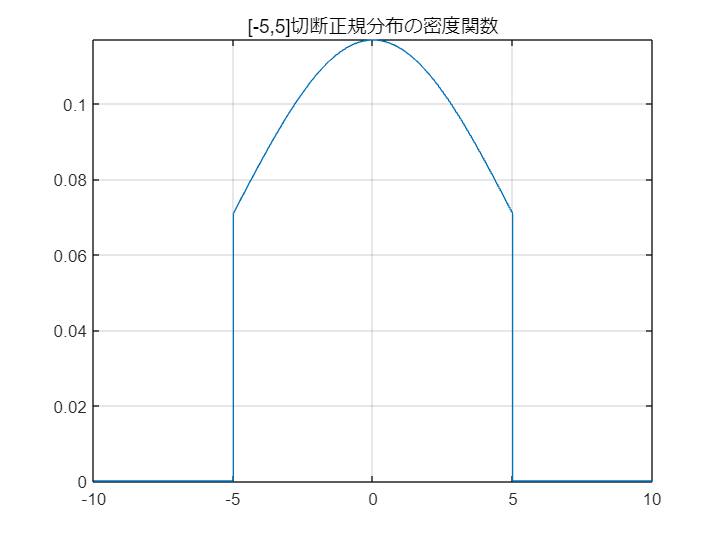

xmin = -5;
xmax = 5; 
mu = 0.0;
sig = 5; 
% 密度関数の定義
isInRange = @(x) and(ge(x,xmin),le(x,xmax)); % x \in [xmin,xmax]なら１、それ以外では０を返す
p = @(x) isInRange(x).*(1/(normcdf(xmax,mu,sig)-normcdf(xmin,mu,sig))*exp(-0.5*((x-mu)/sig).^2)/(sqrt(2*pi)*sig));
nfig = 1; 
figure(nfig);fplot(p,[-10,10]);grid; title('[-5,5]切断正規分布の密度関数');

切断正規分布の密度関数を使って以下のように変形することができる。


$$\int_{xmin}^{xmax} f(x) {\rm d}x = \int_{xmin}^{xmax} f(x) {\rm e}^{\frac{1}{2} \left( \frac{x-\mu}{\sigma}\right)^2} \left( N(xmax,\mu,\sigma)-N(xmin,\mu,\sigma)\right) \sqrt{2\pi} \sigma  \frac{1}{N(xmax,\mu.\sigma)-N(xmin,\mu,\sigma)} \frac{{\rm e}^{-\frac{1}{2} \left( \frac{x-\mu}{\sigma}\right)^2}}{\sqrt{2\pi} \sigma } {\rm d} x  \\ = \int_{xmin}^{xmax}f(x){\rm e}^{\frac{1}{2} \left( \frac{x-\mu}{\sigma}\right)^2} \left(N(xmax,\mu,\sigma)-N(xmin,\mu,\sigma) \right) \sqrt{2\pi} \sigma \times p(x) {\rm d}x \\ = \mathbb{E} \left[ f(X) {\rm e}^{\frac{1}{2} \left( \frac{X-\mu}{\sigma}\right)^2} \left( N(xmax,\mu,\sigma)-N(xmin,\mu,\sigma)\right) \sqrt{2\pi} \sigma\right]$$


ただし、$X \sim {\rm TrN}(\mu,\sigma,[xmin,xmax])$であり、


$${\rm e}^{\frac{1}{2} \left( \frac{X-\mu}{\sigma}\right)^2} \left( N(xmax,\mu,\sigma)-N(xmin,\mu,\sigma)\right) \sqrt{2\pi} \sigma$$


は切断正規分布で評価するための重み付けとなる。

これより、切断正規分布 ${\rm TrN}(\mu,\sigma,[xmin,xmax])$ に従うとして乱数を生成することで期待値を評価すればよい。

#### Matlabでの切断分布に従う乱数の生成方法

Matlabでは切断分布に従う乱数を生成するための関数が用意されている。例えば、範囲が $[a,b]$であり平均 $\mu = \frac{a+b}{2}$, 標準偏差 $\sigma = \frac{b-a}{2}$の切断正規分布に従う乱数の生成方法は以下の通りである。

数値例として $\int_{-5}^5 x^2 {\rm d} x$を切断正規分布によるモンテカルロ・シミュレーション(乱数の数 10000)で求める。ただし、 $\mu=0,\sigma=5$とする。

 参考として解析解、一様分布による結果を合わせて示す。

vfn = getMyRNG(xmin,xmax,'TruncatedNormal'); % [xmin,xmax]での切断正規分布に従う乱数を生成する関数の作成
xsn = vfn(Nsim,1); 
mn = (xmin+xmax)/2; 
sig = (xmax-xmin)/2; 
vTruncatedNormal = mean(f(xsn).*exp(1/2*((xsn-mn)/sig).^2))*sqrt(2*pi)*sig*(normcdf(xmax,mn,sig)-normcdf(xmin,mn,sig)); 
vUniform = vMC; 
rst = table(vAnalytical,vUniform,vTruncatedNormal);
disp(rst)

    vAnalytical    vUniform    vTruncatedNormal
    ___________    ________    ________________

      83.333        84.386          84.248     



disp([rst.vUniform-rst.vAnalytical,rst.vTruncatedNormal-rst.vAnalytical]);

    1.0523    0.9151



一様分布、切断正規分布の値は解析解と近いことがわかる。

次はいくつかの例でsectioningによる推定値の信頼区間を計算する。

#### 定積分の計算1

$\int_{-5}^5 x^2 {\rm d} x$を一様分布に従う乱数、切断正規分布に従う乱数によるモンテカルロ・シミュレーションで求める。ただし、 $\mu=0,\sigma=5$とする。推定値の信頼区間はSectionningで求め、解析解が信頼区間に入っているか確かめる。一様分布に従う乱数による推定と切断正規分布に従う乱数によるを比べると、推定値はどちらも解析解に近いが一様分布の推定のほうが収束性が良いことがわかる。

解析解

clear;

%% 解析解
f = @(x) x.^2; 
xmin = -5; 
xmax = 5; 
vana = integral(f,xmin,xmax);
disp(vana); 

   83.3333



%% シミュレーションの設定
Nsims = [1000;10000;100000];
Nt = 100; 
alpha = 0.01; 

一様乱数による積分

% [xmin,xmax]一様分布に従う乱数の生成関数
myrnd = getMyRNG(xmin,xmax,'Uniform');
% シミュレーション
lowers1 = zeros(size(Nsims));
uppers1 = zeros(size(Nsims));
for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        vs(jloop) = mean(f(myrnd(Nsim,1)))*(xmax-xmin); 
    end
    rst = estConfidenceInterval(vs,alpha);
    lowers1(iloop) = rst.CILower;
    uppers1(iloop) = rst.CIUpper;
end

切断正規分布による積分

% 切断正規分布に従う乱数の生成関数
mn = (xmin+xmax)/2; 
sig = (xmax-xmin)/2; 
myrnd = getMyRNG(xmin,xmax,'TruncatedNormal');

% シミュレーション
lowers2 = zeros(size(Nsims));
uppers2 = zeros(size(Nsims));

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        xsn = myrnd(Nsim,1); 
        vs(jloop) = mean(f(xsn).*exp(1/2*((xsn-mn)/sig).^2))*sqrt(2*pi)*sig*(normcdf(xmax,mn,sig)-normcdf(xmin,mn,sig)); 
    end
    rst = estConfidenceInterval(vs,alpha);
    lowers2(iloop) = rst.CILower;
    uppers2(iloop) = rst.CIUpper;
end

結果のグラフ表示

nfig = 2; 
figure(nfig); semilogx(Nsims,[uppers1,lowers1],'b*-'); grid; title('シミュレーションによる定積分計算'); hold on;
semilogx(Nsims,[uppers2,lowers2],'g*-'); semilogx(Nsims,vana*ones(size(Nsims)),'r-'); 
legend('一様分布99%上限','一様分布99%下限','切断分布99%上限','切断分布99%下限','解析解','Location','best'); hold off;

#### 定積分の計算2

$\int_0^{xmax} 2x^2 \ {\rm e}^{-2x} {\rm d} x$を $xmax = 10,100,1000, 10000$として モンテカルロ・シミュレーションで求める。推定値の信頼区間はSectionningで求め、数値積分解(Matlabのintegral関数を利用する）が信頼区間に入っているか確かめる。一様分布に従う乱数、切断指数分布に従う乱数で計算してみる。 $xmax$が大きくなると一様乱数による推定は誤差が大きくなるが、切断指数分布に従う乱数による推定では $xmax$の大きさに関係なく誤差はほぼ一定である。これは $2 {\rm e}^{-2x}$が平均0.5の指数分布の密度関数であるため定積分$\int_0^{xmax} 2x^2 \ {\rm e}^{-2x} {\rm d} x$が $X$を切断指数分布に従う確率変数として $\mathbb{E}\left[X^2\right]$を計算することになるからである。

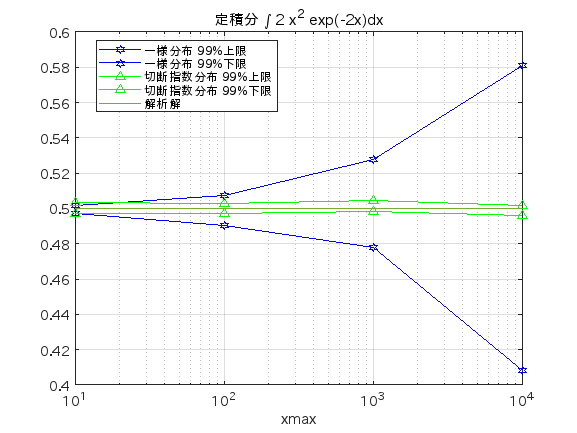

clear;

% 被積分関数の定義
lamb = 2; 
f = @(x) lamb*x.^2 .* exp(-lamb*x);

xmin = 0; 
xmaxs = [10,100,1000,10000]'; % 積分範囲の上限
Nsim = 10000;
Nt = 100;
alpha = 0.01; 

fana = @(xmax) integral(f,xmin,xmax); %解析解の関数
funi = @(xmax) exAuxFun1(f,xmin,xmax,Nsim,Nt,alpha); % 一様乱数による推定
fexp = @(xmax) exAuxFun2(lamb,xmin,xmax,Nsim,Nt,alpha);% 切断指数分布による推定

vanas = zeros(size(xmaxs));
uuppers = zeros(size(xmaxs));
ulowers = zeros(size(xmaxs));
euppers = zeros(size(xmaxs));
elowers = zeros(size(xmaxs));

for iloop = 1:size(xmaxs,1)
    % 解析解
    vanas(iloop) = fana(xmaxs(iloop)); 
    % 一様乱数
    rst = funi(xmaxs(iloop));
    uuppers(iloop) = rst.CIUpper; 
    ulowers(iloop) = rst.CILower; 
    % 切断分布
    rst = fexp(xmaxs(iloop));
    euppers(iloop) = rst.CIUpper; 
    elowers(iloop) = rst.CILower; 
end
nfig = 3; 
figure(nfig); 
semilogx(xmaxs,[uuppers,ulowers],'bh-');grid; title('定積分 \int 2 x^2 exp(-2x)dx');xlabel('xmax'); hold on;
semilogx(xmaxs,[euppers,elowers],'g^-'); semilogx(xmaxs,vanas,'-')
legend('一様分布 99%上限','一様分布 99%下限','切断指数分布 99%上限','切断指数分布 99%下限','解析解','location',"best");
hold off; 

#### 円周率の推定

円周率を積分計算により評価する。下図の塗りつぶされた部分の面積は $\frac{\pi}{4}$であるので$4 \times \int_0^1 \sqrt{1-x^2} {\rm d} x$は円周率となる。

積分をモンテカルロ・シミュレーションで実行して円周率を推定する。推定値の信頼区間はSectionningで求める。

乱数の数を1000,10000,100000、Sectionningでの繰り返し数を10回、100回とした時のそれぞれの信頼区間がどのようになるか確認する。

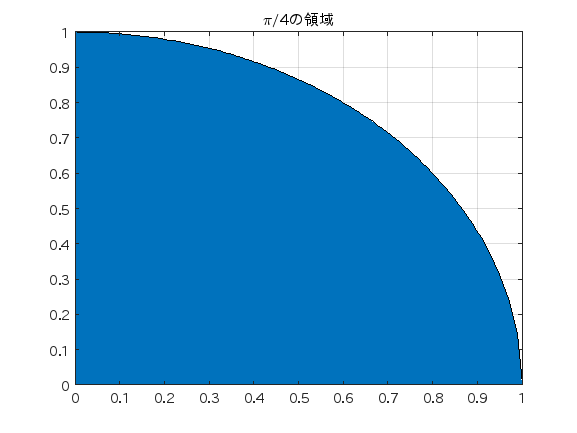

clear;

f = @(x) sqrt(1-x.^2); xs = linspace(0,1,100);
nfig = 3; 
figure(nfig);
area(xs,f(xs));grid; xticks(0:0.1:1.0); title('\pi/4の領域');

Nsims = [1000;10000;100000]; 
Nts = [10;100];
alpha = 0.01; 
for iloop = 1:size(Nsims,1)
    for jloop = 1:size(Nts,1)
        disp("Nsim = " + string(Nsims(iloop)) + ", Nt = " + string(Nts(jloop)));
        disp(exAuxFun3(Nsims(iloop),Nts(jloop),alpha));
        disp(" ");
    end
end

Nsim = 1000, Nt = 10


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    3.1105     3.1742       10      0.01 



Nsim = 1000, Nt = 100


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

     3.139     3.1535      100      0.01 



Nsim = 10000, Nt = 10


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    3.1334     3.1492       10      0.01 



Nsim = 10000, Nt = 100


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    3.1388     3.1444      100      0.01 



Nsim = 100000, Nt = 10


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    3.1385     3.1435       10      0.01 



Nsim = 100000, Nt = 100


    CILower    CIUpper    Ntrial    alpha
    _______    _______    ______    _____

    3.1409     3.1423      100      0.01 



## 2.微分の計算

パラメータに対する感応度計算は実務、研究においてよく行われる。モンテカルロ・シミュレーションでの感応度計算の弱点を理解し、弱点を回避するための手法を確認する。

確率変数 $Y$がパラメータとして $x$を含む、つまり $Y = Y(\omega,x)$とする（ただし、 $\omega \in \Omega$は事象を表す）。このとき $Y$の期待値は $x$の関数であり $f(x) = \mathbb{E}\left[ Y(\omega, x) \right]$とする。

xに関する微分 $\frac{{\rm d} }{{\rm d} x} f(x) = \frac{{\rm d} }{{\rm d}x} \mathbb{E} \left[Y(\omega ,x) \right]$をモンテカルロ・シミュレーションで求める手法を確認する。

#### 2-1.有限差分：前進差分

　有限差分による近似は、微分の定義 $\frac{{\rm d} }{{\rm d} x} f(x) = \lim_{h \rightarrow 0} \frac{f(x+h) - f(x)}{h}$に基づいている。

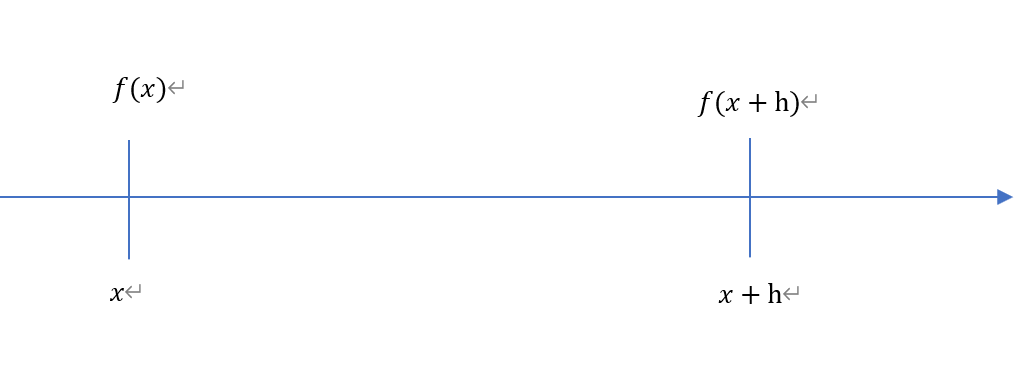

 $f(x+h)$と $f(x)$をそれぞれモンテカルロ・シミュレーションで推定し (推定値を $\hat{f}(x+h), \hat{f}(x)$とする）、 $\frac{{\rm d}}{{\rm d} x}f(x) \simeq \frac{\hat{f}(x+h)-\hat{f}(x)}{h}$と有限差分(前進差分）で微分を近似する。

ここでは、前進差分による近似での誤差について考える。

$f(x+h)$を $x$を基準にテイラー展開すると


$$f(x+h) = f(x) + \frac{{\rm d}}{{\rm d} x} f(x) h + +\frac{1}{2}\frac{{\rm d}^2}{{\rm d} x^2} f(x) h^2  + \mathcal{O}(h^3)$$


となるので、これより


$$\frac{f(x+h)-f(x)}{h} = \frac{{\rm d}}{{\rm d} x}f(x) + \frac{1}{2} \frac{{\rm d}^2}{{\rm d}x^2}f(x) h + \mathcal{O}(h^2)$$


となる。これより高次項を無視すると離散近似による誤差は $\frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2}f(x) h$ である。

また、モンテカルロ・シミュレーションでの推定誤差を


$$\hat{f}(x+h) = f(x+h) + \varepsilon_1$$



$$\hat{f}(x) = f(x) + \varepsilon_2$$



$$\varepsilon_1 \sim N(0,\sigma), \varepsilon_2 \sim N(0,\sigma), {\rm Corr}\left( \varepsilon_1, \varepsilon_2\right) = \rho$$


とする。 $\hat{f}(x+h), \hat{f}(x)$の推定誤差の分散は同じとしている。

以上よりモンテカルロ・シミュレーションでの有限差分による微分の推定は


$$\frac{\hat{f}(x+h)-\hat{f}(x)}{h} = \frac{f(x+h)-f(x)}{h} + \frac{\varepsilon_1 - \varepsilon_2}{h} = \frac{{\rm d}}{{\rm d}x}f(x) + \frac{1}{2}\frac{{\rm d}^2}{{\rm d} x^2} f(x) h + \frac{\varepsilon_1-\varepsilon_2}{h} = \frac{{\rm d}}{{\rm d}x} f(x) + \mathcal{\epsilon}$$


と表される。誤差項は


$$\mathbb{\epsilon} = \frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2} f(x) h + \frac{\varepsilon_1-\varepsilon_2}{h}$$


である。第１項が離散近似誤差、第２項がモンテカルロ・シミュレーション誤差である。誤差項の期待値は $\mathbb{E}\left[\mathcal{\epsilon}\right]=\frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2}f(x) h \ne 0$であり、誤差項はバイアスを持つことになる。

誤差の二乗の期待値は


$$\mathbb{E}\left[\mathcal{\epsilon}^2 \right] = \left(\frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2}f(x) \right)^2 h^2 + 2\frac{\sigma^2 ( 1- \rho)}{h^2}$$


となる。離散近似誤差は $h$が小さくなると小さくなり、モンテカルロ・シミュレーション誤差は $h$が大きくなると小さくなる。 

誤差二乗を最小にする $h$を $h^*$とすると


$$h^* = \left(8 \frac{\sigma^2(1-\rho)}{\left(\frac{{\rm d}^2}{{\rm d} x^2}f(x) \right)^2} \right)^{\frac{1}{4}}$$


である。 $\frac{{\rm d}^2}{{\rm d}x^2}f(x)$ は未知であるので具体的に計算することはできないが、誤差二乗を最小にする $h$が存在することが示されたことになる。

#### 2-2.有限差分：中心差分

　微分の有限差分による近似には前進差分だけでなく中心差分がある。中心差分では微分を $\frac{f\left(x+\frac{h}{2}\right)-f\left(x-\frac{h}{2}\right) }{h}$と近似する。

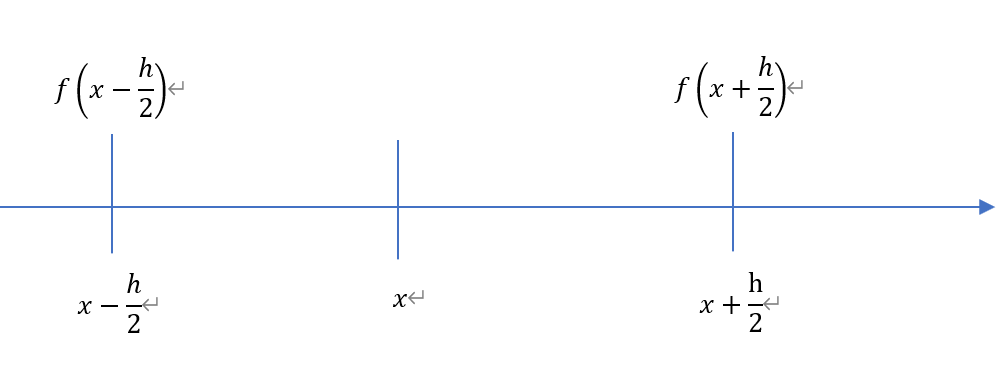

前進差分と同様に中心差分での誤差評価を行う。

xを基準にしたテイラー展開により


$$f\left( x + \frac{h}{2}\right) = f(x) + \frac{{\rm d}}{{\rm d} x} f(x) \frac{h}{2} + \frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2}f(x) \left( \frac{h}{2} \right)^2 + \frac{1}{6} \frac{{\rm d}^3}{{\rm d}x^3}f(x) \left(\frac{h}{2} \right)^3 + \mathcal{O}(h^4)$$



$$f\left( x - \frac{h}{2}\right) = f(x) - \frac{{\rm d}}{{\rm d} x} f(x) \frac{h}{2} + \frac{1}{2}\frac{{\rm d}^2}{{\rm d}x^2}f(x) \left( \frac{h}{2} \right)^2 - \frac{1}{6} \frac{{\rm d}^3}{{\rm d}x^3}f(x) \left(\frac{h}{2} \right)^3 + \mathcal{O}(h^4)$$


となる。これより


$$\frac{f\left(x+\frac{h}{2}\right)-f\left(x-\frac{h}{2}\right)}{h} = \frac{{\rm d}}{{\rm d} x}f(x) + \frac{1}{24} \frac{{\rm d}^3}{{\rm d} x^3}f(x) h^2$$


である。モンテカルロ・シミュレーションによる推定を


$$\hat{f}\left(x+\frac{h}{2}\right) = f\left(x+\frac{h}{2}\right) + \varepsilon_1$$



$$\hat{f}\left(x-\frac{h}{2}\right) = f\left(x-\frac{h}{2}\right) + \varepsilon_2$$



$$\varepsilon_1 \sim N(0,\sigma), \varepsilon_2 \sim N(0,\sigma), {\rm Corr}\left( \varepsilon_1, \varepsilon_2\right) = \rho$$


とすると、中心差分でのモンテカルロ・シミュレーションによる推定は


$$\frac{\hat{f}\left(x+\frac{h}{2}\right)-\hat{f}\left(x-\frac{h}{2}\right)}{h} = \frac{f\left(x+\frac{h}{2}\right)-f\left(x-\frac{h}{2}\right)}{h} + \frac{\varepsilon_1 - \varepsilon_2}{h} = \frac{{\rm d}}{{\rm d}x}f(x) + \frac{1}{24}\frac{{\rm d}^3}{{\rm d}x^3}f(x) h^2 + \frac{\varepsilon_1 - \varepsilon_2}{h} = \frac{{\rm d}}{{\rm d} x}f(x) + \mathcal{\epsilon}$$


と表される。誤差項は


$$\mathcal{\epsilon} = \frac{1}{24}\frac{{\rm d}^3}{{\rm d} x^3}f(x) h^2 + \frac{\varepsilon_1-\varepsilon_2}{h}$$


である。誤差の第１項が離散近似誤差、第２項がモンテカルロ・シミュレーション誤差である。誤差項の期待値は $\mathbb{E}\left[\mathcal{\epsilon}\right]=\frac{1}{24}\frac{{\rm d}^3}{{\rm d} x^3}f(x) h^2 \ne 0$であり、誤差項はバイアスを持つことになる。

誤差の二乗の期待値は


$$\mathbb{E}\left[\mathcal{\epsilon}^2 \right] = \left(\frac{1}{24}\frac{{\rm d}^3}{{\rm d}x^3}f(x) \right)^2 h^4 + 2\frac{\sigma^2(1-\rho)}{h^2}$$


となる。誤差の二乗の期待値を最小にする $h$を $h^*$とすると


$$h^* = \left( 576 \frac{\sigma^2(1-\rho)}{\left(\frac{{\rm d}^3}{{\rm d}x^3} f(x)\right)^2} \right)^{\frac{1}{6}}$$


となる。 $\frac{{\rm d}^3}{{\rm d}x^3}f(x)$ は未知であるので前進差分と同様に $h^*$を具体的に計算することはできないが、最適な $h^*$が存在することはわかる。

**モンテカルロ誤差の低減方法**

前進差分、中心差分ともに誤差の分散のうちモンテカルロ・シミュレーションによる誤差は $2 \frac{\sigma^2 (1 -\rho) }{h^2}$である。 $\rho$は２つの誤差項 $\varepsilon_1, \varepsilon_2$の相関係数である。

前進差分では$\hat{f}(x), \hat{f}(x+h)$のシミュレーション、中心差分では $\hat{f}\left(x - \frac{h}{2} \right), \hat{f}\left(x+\frac{h}{2}\right)$のシミュレーションでの乱数生成を独立に行うと $\rho \simeq 0$であり、同じ乱数列を用いると $\rho >0$となる。

よって、同じ乱数列を用いるほうが、モンテカルロ・シミュレーションによる誤差 $2 \frac{\sigma^2 (1 -\rho) }{h^2}$は小さくなることが期待される。

#### 2-3. 数値例

例として、 $X$を確率変数として2つの関数 $f(\sigma) = \mathbb{E}\left[{\rm e}^{\sigma X} \right]$, $g(\sigma)=\mathbb{E}\left[\max \left({\rm e}^{\sigma X},1\right) \right]$を用いる。それぞれの $\sigma$に関する 微分 $\frac{\partial}{\partial \sigma} f(\sigma), \frac{\partial }{\partial \sigma} g(\sigma)$をモンテカルロ・シミュレーションで評価する。

確率変数$X$は標準正規分布に従うと仮定すると $f(\sigma) ={\rm e}^{\frac{1}{2} \sigma^2}$, $g(\sigma)={\rm e}^{\frac{1}{2}\sigma^2}\left(1- N(-\sigma)\right)+\frac{1}{2}$と解析的に解くことができ、微分は


$$\frac{{\rm d}}{{\rm d} \sigma}f(\sigma) =\sigma {\rm e}^{\frac{1}{2}\sigma^2}$$



$$\frac{{\rm d}}{{\rm d}\sigma}g(\sigma)=\sigma {\rm e}^{\frac{1}{2}\sigma^2}\left(1- N(-\sigma)\right) + \frac{1}{\sqrt{2\pi}}$$


となる。 $\sigma = 1$のときの解析解による微分値$\left.\frac{{\rm d}}{{\rm d}\sigma} f(\sigma) \right\vert_{\sigma=1}$と$\left.\frac{{\rm d}}{{\rm d}\sigma} g(\sigma) \right\vert_{\sigma=1}$がモンテカルロ・シミュレーションの推定値の信頼区間に入っているか確認する。

　前進差分、中心差分において差分の幅 $h$を変化させて$\frac{\partial}{\partial \sigma} f(\sigma), \frac{\partial }{\partial \sigma} g(\sigma)$の推定値の信頼区間が変化するか確認する。解析解の値が信頼区間に含まれていることを合わせて確認する。

また、前進差分、中心差分において誤差 $\varepsilon_1,\varepsilon_2$の相関 $\rho$が１に近いほど誤差の二乗の期待値が小さくなる。よって、 $\hat{f}(x+h), \hat{f}(x)$の推定(前進差分)、 $\hat{f}\left(x+\frac{h}{2}\right),\hat{f}\left(x-\frac{h}{2}\right)$の推定(中心差分)において同じ乱数列を用いると $\rho$を１に近づけることができる。異なる乱数列を用いる場合と同じ乱数列を用いる場合での推定値の信頼区間を比較する。

**前進差分**

clear;

%　被積分関数
f = @(sig,X) exp(sig.*X);
g = @(sig,X) max(exp(sig.*X),1); 

% 解析解設定
dfana = @(sig) sig*exp(0.5*sig.^2);
dgana = @(sig) sig.*exp(0.5*sig.^2).*(1-normcdf(-sig)) + 1/sqrt(2*pi);
sig = 1; 
dfv = dfana(sig); 
dgv = dgana(sig); 

% シミュレーション設定
Nsim = 10000; 
Nt = 10; 
alpha = 0.01; 
hs = (0.01:0.01:0.1)';

・乱数列を変える場合

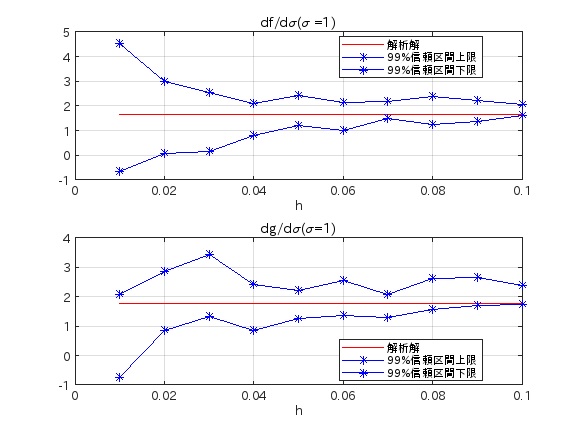

isReUse = false;
fdmType = "FD"; 
[flowers,fuppers] = exAuxFun4(f,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);
[glowers,guppers] = exAuxFun4(g,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);

nfig = 4; 
figure(nfig);subplot(211); plot(hs,dfv*ones(size(hs)),'r-');grid; xlabel('h'); title('df/d\sigma(\sigma =1)'); hold on;
plot(hs,[fuppers,flowers],'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;
figure(nfig);subplot(212); plot(hs,dgv*ones(size(hs)),'r-');grid; xlabel('h'); title('dg/d\sigma(\sigma=1)'); hold on;
plot(hs,[guppers,glowers],'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off; 

・乱数列を同じにする場合

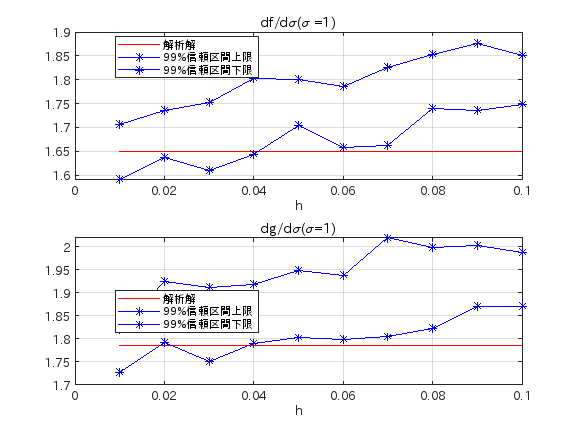

isReUse = true;
fdmType = "FD"; 
[flowers,fuppers] = exAuxFun4(f,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);
[glowers,guppers] = exAuxFun4(g,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);

nfig = 5; 
figure(nfig);subplot(211); plot(hs,dfv*ones(size(hs)),'r-');grid; xlabel('h'); title('df/d\sigma(\sigma =1)'); hold on;
plot(hs,fuppers,'b*-'); plot(hs,flowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;
figure(nfig);subplot(212); plot(hs,dgv*ones(size(hs)),'r-');grid; xlabel('h'); title('dg/d\sigma(\sigma=1)'); hold on;
plot(hs,guppers,'b*-'); plot(hs,glowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;

**中心差分**

・乱数列を変える場合

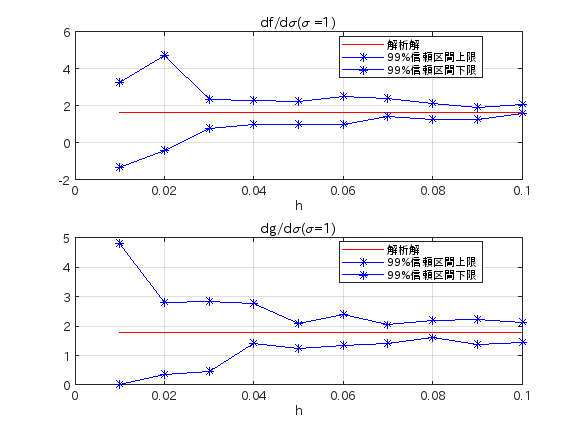

isReUse = false;
fdmType = "CD"; 
[flowers,fuppers] = exAuxFun4(f,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);
[glowers,guppers] = exAuxFun4(g,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);

nfig = 6;
figure(nfig);subplot(211); plot(hs,dfv*ones(size(hs)),'r-');grid; xlabel('h'); title('df/d\sigma(\sigma =1)'); hold on;
plot(hs,fuppers,'b*-'); plot(hs,flowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;
figure(nfig);subplot(212); plot(hs,dgv*ones(size(hs)),'r-');grid; xlabel('h'); title('dg/d\sigma(\sigma=1)'); hold on;
plot(hs,guppers,'b*-'); plot(hs,glowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;

・乱数列を同じにする場合

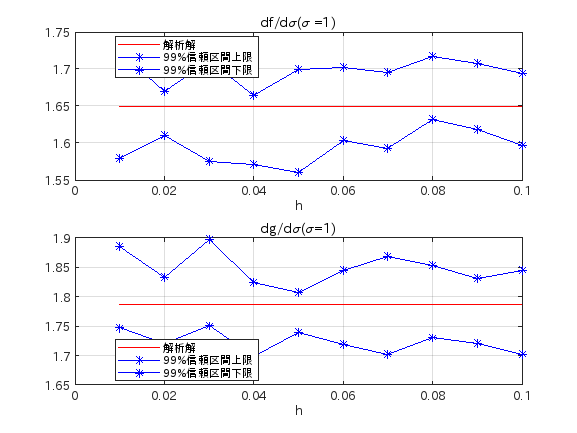

isReUse = true;
fdmType = "CD"; 
[flowers,fuppers] = exAuxFun4(f,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);
[glowers,guppers] = exAuxFun4(g,sig,hs,Nsim,Nt,alpha,isReUse,fdmType);

nfig = 7;
figure(nfig);subplot(211); plot(hs,dfv*ones(size(hs)),'r-');grid; xlabel('h'); title('df/d\sigma(\sigma =1)'); hold on;
plot(hs,fuppers,'b*-'); plot(hs,flowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;
figure(nfig);subplot(212); plot(hs,dgv*ones(size(hs)),'r-');grid; xlabel('h'); title('dg/d\sigma(\sigma=1)'); hold on;
plot(hs,guppers,'b*-'); plot(hs,glowers,'b*-'); legend('解析解','99%信頼区間上限','99%信頼区間下限','location',"best");
hold off;

ここでの実験では、前進差分では差分幅が大きくなるとバイアスが出てきている。

中心差分で同じ乱数列を用いる方法が最も良い推定方法となっていることがわかる。

#### 2-4.パスごとの微分

$Y(\omega,x)$が $x$に関して微分可能であり期待値と微分の順序が交換可能であるとき


$$\frac{{\rm d}}{{\rm d}x}f(x) = \frac{{\rm d}}{{\rm d}x} \mathbb{E}\left[ Y(\omega,x) \right] = \mathbb{E}\left[\frac{{\rm d}}{{\rm d}x} Y(\omega ,x) \right]$$


となる。 $\omega_1,\cdots,\omega_N$をサンプリングして $\frac{1}{N} \sum_{i=1}^{N} \frac{{\rm d}}{{\rm d}x} Y(\omega_i,x)$を計算することで微分値を推定することができる。

例として$f(x) = \mathbb{E}\left[{\rm e}^{x Y} \right]$とすると ${\rm e}^{xY}$は $x$で微分可能であるので $\frac{{\rm d}}{{\rm d}x}f(x) = \mathbb{E}\left[\frac{{\rm d}}{{\rm d}x} {\rm e}^{x Y}\right] = \mathbb{E}\left[ Y {\rm e}^{xY}\right]$となる。よって、 $Y_1,\cdots,Y_N$をサンプリングして $\frac{1}{N} \sum_{i=1}^{N} Y_i {\rm e}^{x Y_i}$を計算すれば良い。

この方法は１回の推定だけでよいが、ファイナンスの問題では微分不可能な点を含むことが多く利用できる場面は限られている。

#### 2-5.数値例

$f(\sigma) = \mathbb{E}\left[{\rm e}^{\sigma X}\right]$はパスごとに微分可能であり、 $\frac{{\rm d}}{{\rm d}\sigma}f(\sigma) = \mathbb{E}\left[X {\rm e}^{\sigma X} \right]$となる。 $X$が標準正規分布に従うとして $\sigma = 1$での右辺の期待値をモンテカルロ・シミュレーションで評価する。

解析解の値が推定の信頼区間に入っていることを確認する。

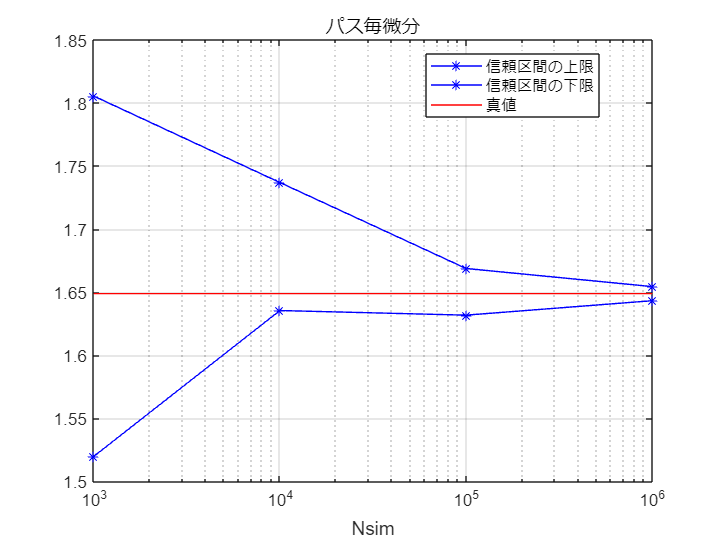



Nsims = [1000,10000,100000,1000000]';
Nt = 10; 
alpha = 0.01;

upper = zeros(size(Nsims));
lower = zeros(size(Nsims));

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);

    vs = zeros(Nt,1);
    for jloop = 1:Nt
        xs = randn(Nsim,1);
        vs(jloop) = mean(xs.*exp(xs));
    end
    rst = estConfidenceInterval(vs,alpha);
    upper(iloop) = rst.CIUpper;
    lower(iloop) = rst.CILower;
end
nfig = 9;
figure(nfig); semilogx(Nsims,[upper,lower],'b*-'); grid; title('パス毎微分'); xlabel('Nsim'); hold on; 
semilogx(Nsims,dfv*ones(size(Nsims)),'r-'); 
legend('信頼区間の上限','信頼区間の下限','真値','location',"best");hold off;

#### 2-6.Likelihood method

$Y(\omega,x)$の期待値計算が以下のように関数 $h(y)$と密度関数 $p(y,x)$を用いて計算できると仮定する。


$$f(x) = \mathbb{E}\left[Y(\omega,x)\right] = \int_{\Omega} h(y) p(y,x) {\rm d}y$$


このとき、 $x$に関する微分計算は


$$\frac{{\rm d}}{{\rm d}x}f(x) = \int_{\Omega} h(y) \frac{{\rm d}}{{\rm d}x} p(y,x) {\rm d} x = \int_{\Omega} h(y) \frac{\frac{{\rm d}}{{\rm d}x}p(y,x)}{p(y,x)} p(y,x) {\rm d}y = \mathbb{E}\left[h(Y) \mathcal{L}(Y,x) \right]$$



$$Y \sim p(y,x)$$



$$\mathcal{L}(y,x) = \frac{{\frac{{\rm d}}{{\rm d}x}p(y,x)}}{p(y,x)}$$


となる。 この方法では $h(y)$が微分可能である必要はないので、パスごとの微分ができない問題に適用できる。

適切な $h(y), p(y,x)$を見つけることができれば、 $Y_1,\cdots,Y_N$をサンプリングして $\frac{1}{N}\sum_{i=1}^{N} h(Y_i) \mathcal{L}(Y_i,x)$を算出することで微分値を推定することができる。

例として $f(x)=\mathbb{E}\left[\max \left({\rm e}^{x Y},1\right) \right]$とすると $\max\left({\rm e}^{x Y},1 \right)$は $xY = 0$で微分可能でないので「パスごと微分」の方法は使えない。しかし、 $Z = xY$とし $Z$の確率密度関数を $p(z,x)$とすると


$$f(x) = \mathbb{E}\left[ \max\left( {\rm e}^{Z},1\right) \right] = \int_{\Omega} \max\left( e^z, 1\right) p(z,x) {\rm dz}$$


となるので


$$\frac{{\rm d}}{{\rm d}x}f(x) = \int_{\Omega} \max\left({\rm e}^z,1\right) \frac{{\rm d}}{{\rm d}x}p(z,x) {\rm d}z = \int_{\Omega} \max\left({\rm e}^z,1\right) \frac{\frac{{\rm d}}{{\rm d}x}p(z,x)}{p(z,x)} p(z,x) {\rm d}z = \mathbb{E}\left[\max\left({\rm e}^Z,1 \right) \frac{\frac{{\rm d}}{{\rm d} x}p(Z,x)}{p(Z,x)} \right]$$


となる。これより、 $Z_1,\cdots,Z_N \sim p(z,x)$をサンプリングして $\frac{1}{N}\sum_{i=1}^{N} \max\left({\rm e}^{Z_i},1\right) \frac{\frac{{\rm d}}{{\rm d}x}p(Z_i,x)}{p(Z_i,x)}$を計算することで微分値を計算することが出来る。

この方法は、パスごとの微分よりも汎用的であるが、密度関数を明示的に計算する必要がある点が実務的な制約となる。

#### 2-7.数値例

$\max\left({\rm e}^{\sigma X},1\right)$は微分できない点があるので、 $g(\sigma)=\mathbb{E}\left[\max\left({\rm e}^{\sigma X},1\right) \right]$はパスごとの微分ができない。

ところで、 $X$が標準正規分布に従っているので $Y = \sigma X$は平均0、分散 $\sigma^2$の正規分布に従うことから


$$g(\sigma)=\mathbb{E}\left[\max\left({\rm e}^{Y},1\right) \right] = \int_{-\infty}^{\infty} \max\left(e^y,1\right) \frac{1}{\sqrt{2\pi}\sigma}{\rm e}^{-\frac{1}{2} \frac{y^2}{\sigma^2}} {\rm d}y$$


と表すことが出来る。これより


$$\frac{{\rm d}}{{\rm d}\sigma}g(\sigma) = \int_{-\infty}^{\infty} \max\left({\rm e}^{y},1\right)\left( \frac{y^2}{\sigma^3}-\frac{1}{\sigma}\right) \frac{1}{\sqrt{2\pi}\sigma}{\rm e}^{-\frac{1}{2}\frac{y^2}{\sigma^2}} {\rm d} y = \mathbb{E}\left[ \max\left({\rm e}^Y,1\right) \left(\frac{Y^2}{\sigma^3}-\frac{1}{\sigma}\right)\right]$$


となる。ただし、 $Y\sim N(0,\sigma^2)$である。 $Y_1,\cdots,Y_N$とサンプリングして $\frac{1}{N}\sum_{i=1}^{N}\max\left({\rm e}^{Y_i},1 \right)\left( \frac{Y_i^2}{\sigma^3}-\frac{1}{\sigma}\right)$を計算することで微分値を推定することができる。

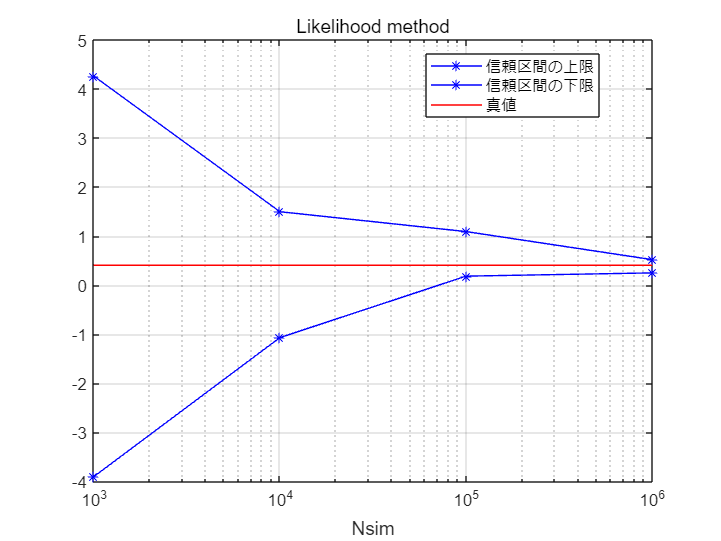



Nsims = [1000,10000,100000,1000000]'; 
Nt = 10; 
alpha = 0.01; 
sig = 0.01; 
dgv = dgana(sig); 
upper = zeros(size(Nsims));
lower = zeros(size(Nsims));

ftmp = @(y,sig) max(exp(y),1).*(y.^2./sig.^3 - 1/sig); 

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs = zeros(Nt,1); 
    for jloop = 1:Nt
        vs(jloop) = mean(ftmp(sig*randn(Nsim,1),sig)); 
    end
    rst = estConfidenceInterval(vs,alpha);
    upper(iloop) = rst.CIUpper;
    lower(iloop) = rst.CILower; 
end
nfig = 10; 
figure(nfig); semilogx(Nsims,[upper,lower],'b*-');grid;title('Likelihood method'); xlabel('Nsim'); hold on; 
semilogx(Nsims,dgv*ones(size(Nsims)),'r-'); 
legend('信頼区間の上限','信頼区間の下限','真値','location',"best");hold off;

### 3.分散低減法Ⅰ

モンテカルロ・シミュレーションでは必ず推定誤差が生じる。推定誤差を小さくする簡単な方法は試行回数を増やすことであるが誤差を $\frac{1}{10}$倍にするためには試行回数を 100倍にする必要がある。試行回数を増やさずに推定誤差を減らす方法がいくつか提案されており、それらをまとめて分散低減法と呼んでいる。万能な方法はなく、それぞれに効果が発揮できる状況があるので、自分が解くべき問題で有効かどうかは都度検討する必要がある。手法の条件に適合していると相応に効果が期待できる。

#### 3-1. Antithetic Sampling（負の相関法）

モンテカルロ・シミュレーションで生成する乱数が従う確率分布の分布関数とその逆関数が簡単に計算できる場合に適用できる方法である。確率分布の分布関数を $F(x)=\mathbb{P}(X \le x)$として、 $\varphi(x) = F^{-1}\left(1-F(x))$と $\varphi(x)$を定義する。確率分布 $F$に従う確率変数を $X$とすると $F(X)$は 区間$[0,1]$の一様乱分布に従うので、 $1-F(X)$も区間 $[0,1]$の一様分布に従う。よって、 $\varphi(X) = F^{-1}\left(1-F(X)\right)$は確率分布 $F$に従う確率変数であることがわかる。ゆえに $X$の実現値 $X_i$に対して $\varphi(X_i)$も $X$の実現値と見なすことができる。

このような状況ではモンテカルロ・シミュレーションを次のように実行することができる。


$$\mathbb{E}\left[f(X)\right] \simeq \frac{1}{N/2} \sum_{i=1}^{N/2} \frac{f(X_i) + f(\varphi(X_i))}{2} = \frac{1}{N} \sum_{i=1}^{N/2} \left\{ f(X_i) + f(\varphi(X_i))\right\}$$


誤差の分散は


$${\rm Var}\left[ \frac{1}{N} \sum_{i=1}^{N/2} \left\{ f(X_i) + f(\varphi(X_i))\right\} \right] = \frac{1}{N^2} \sum_{i=1}^{N/2} \left\{{\rm Var}\left[f(X_i) \right] + {\rm Var}\left[f(\varphi(X_i)) \right] + 2{\rm Cov}\left[f(X_i),f(\varphi(X_i)) \right]  \right\} = \frac{1}{N} {\rm Var}\left[f(X) \right] + \frac{1}{N} {\rm Cov} \left[ f(X), f(\varphi(X))\right]$$


となる。通常のモンテカルロ・シミュレーションでの誤差の分散は


$${\rm Var}\left[\frac{1}{N}\sum_{i=1}^{N} f(X_i)\right] = \frac{1}{N} {\rm Var}\left[f(X) \right]$$


である。よって、 $\frac{1}{N} {\rm Cov} \left[ f(X), f(\varphi(X))\right] \lt 0$となる、つまり、 $f(X)$と $f(\varphi(X)$との相関が負であれば誤差の分散が通常のモンテカルロ・シミュレーションより小さくなることがわかる。

$f(X)$と $f(\varphi(X)$との相関は負になるとは限らないことに注意する。

$\varphi(x)$**の例**

 $X$が区間 $[0,1]$の一様分布に従うときは $F(x) = x$, $F^{-1}(x) = x$であるので 、


$$\varphi(x) = F^{-1}(1-F(x)) = F^{-1}(1-x) = 1-x$$


となる。よって、 $\mathbb{E}\left[f(X)\right] \simeq \frac{1}{N}\sum_{i=1}^{N/2} \left\{ f(X_i) + f(1-X_i)\right\}$となる。

 $X$が標準正規分布に従うときは、 $p(x) = \frac{1}{\sqrt{2\pi}}{\rm e}^{-\frac{1}{2}x^2}$とすると $F(x) = \int_{-\infty}^{x} p(x) {\rm d}x$であり$1-F(x) = 1 - \int_{-\infty}^{x} p(x) {\rm d}x = \int_{x}^{\infty}p(x) {\rm d} x = \int_{-\infty}^{-x} p(x) {\rm d}x = F(-x)$となる。よって、 


$$\varphi(x) = F^{-1}(1-F(x)) = F^{-1}(F(-x)) = -x$$


となる。ゆえに、 $\mathbb{E}\left[f(X)\right] \simeq \frac{1}{N} \sum_{i=1}^{N/2}\left\{f(X_i) + f(-X_i)\right\}$となる。

 $X$が強度 $\lambda$の指数分布に従うときは、 $F(x) = 1 - {\rm e}^{-\lambda x}$であるので、 $F^{-1}(x) = -\frac{1}{\lambda} \log\left(1-x\right)$であり $1-F(x)={\rm e}^{-\lambda x}$である。よって、

 
$$\varphi(x) = F^{-1}(1-F(x)) = F^{-1}\left({\rm e}^{-\lambda x}\right) = -\frac{1}{\lambda}\log\left(1-{\rm e}^{-\lambda x}\right)$$


となる。ゆえに、 $\mathbb{E}\left[f(X)\right] \simeq \frac{1}{N} \sum_{i=1}^{N/2} \left\{ f(X_i) + f\left(-\frac{1}{\lambda}\log\left(1-{\rm e}^{-\lambda X_i}\right)\right)\right\}$となる。

**・標準正規乱数のモーメントの推定**

$X$を標準正規分布に従う確率変数として4次までのモーメント $(\mathbb{E}[X],\mathbb{E}[X^2],\mathbb{E}[X^3],\mathbb{E}[X^4])$をモンテカルロ・シミュレーションで求める。

Antithetic Samplingでは 標準正規分布に従う乱数$X_i$に対して $-X_i$を用いる。よって、


$$\mathbb{E}[X] \simeq \frac{1}{\frac{N}{2}} \sum_{i=1}^{\frac{N}{2}} \frac{X_{i}-X_{i}}{2} = 0$$



$$\mathbb{E}[X^2] \simeq \frac{1}{\frac{N}{2}} \sum_{i=1}^{\frac{N}{2}} \frac{X_i^2+(-X_i)^2}{2} = \frac{1}{\frac{N}{2}}\sum_{i=1}^{\frac{N}{2}}X_i^2$$



$$\mathbb{E}[X^3] \simeq \frac{1}{\frac{N}{2}} \sum_{i=1}^{\frac{N}{2}} \frac{X_i^3 + (-X_i)^3}{2} = 0$$



$$\mathbb{E}[X^4] \simeq \frac{1}{\frac{N}{2}} \sum_{i=1}^{\frac{N}{2}} \frac{X_i^4+(-X_i)^4}{2} = \frac{1}{\frac{N}{2}}\sum_{i=1}^{\frac{N}{2}} X_i^4$$


となる。これより奇数次のモーメントはシミュレーションを行う必要がなく０とわかり（つまり、分散がゼロ）、偶数次のモーメントは通常のモンテカルロ・シミュレーションと同じ分散となることがわかる。この例（極端ではあるが）より、Antithetic Samplingは有効な場合と効果がない場合があることがわかる。

#### 3-2.数値例

・$\pi$の推定

$\pi$のモンテカルロ・シミュレーションでの推定にAntitethic Samplingを適用する。


$$\pi = 4\times \int_{0}^{1} \sqrt{1-x^2} {\rm d}x = 4\times \mathbb{E}\left[ \sqrt{1-X^2} \right]$$
 

$X\sim [0,1]$一様分布に従う確率変数

であるので、モンテカルロ・シミュレーションでの推定値を $\hat{\pi}$とすると


$$\hat{\pi} = \simeq \frac{4}{N} \sum_{i=1}^N \sqrt{1-X_i^2}$$


$X_i$は $[0,1]$の一様分布に従う乱数である。

Antithetic Samplingでは $[0,1]$の一様分布に従う乱数$X_i$に対して $1-X_i$を用いる。よって、Antithetic Samplingでの推定値を $\hat{\pi}_{AS}$とすると


$$\hat{\pi}_{AS} \simeq \frac{4}{\frac{N}{2}} \sum_{i=1}^{\frac{N}{2}} \frac{\sqrt{1-X_i^2}+\sqrt{1-(1-X_i)^2}}{2}$$


となる。

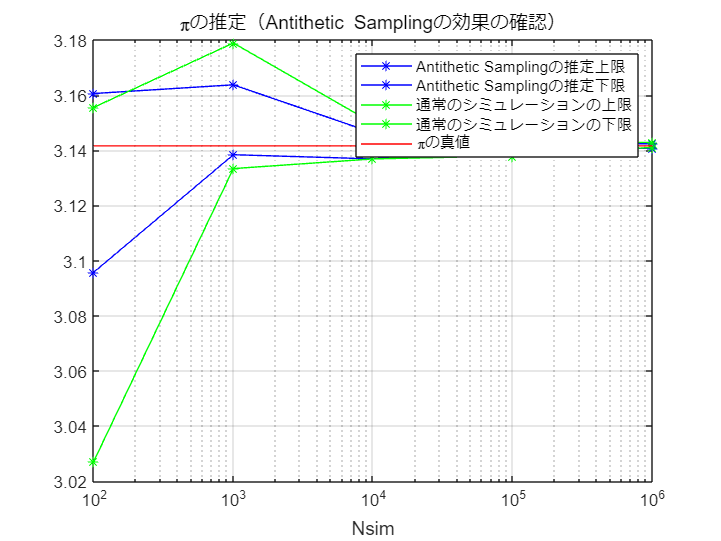

clear;

Nsims = [100,1000,10000,100000,1000000]';
Nt = 10; 
alpha = 0.01; 

upper1 = zeros(size(Nsims));
upper2 = zeros(size(Nsims));
lower1 = zeros(size(Nsims));
lower2 = zeros(size(Nsims));

% 被積分関数
f = @(x) 4*sqrt(1-x.^2);

for iloop = 1:size(Nsims,1)
    Nsim = Nsims(iloop);
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    for jloop = 1:Nt
        rv = rand(Nsim/2,1); 
        % Antithetic Sampling
        vs1(jloop,1) = mean(1/2*(f(rv)+f(1-rv)));
        % 通常のモンテカルロ・シミュレーション
        vs2(jloop,1) = mean(f([rv;rand(Nsim/2,1)]));
    end
    rst = estConfidenceInterval(vs1,alpha);
    upper1(iloop,1) = rst.CIUpper; 
    lower1(iloop,1) = rst.CILower; 
    
    rst = estConfidenceInterval(vs2,alpha);
    upper2(iloop,1) = rst.CIUpper; 
    lower2(iloop,1) = rst.CILower; 
end
nfig = 11;
figure(nfig);semilogx(Nsims,[upper1,lower1],'b*-');grid; title('\piの推定（Antithetic Samplingの効果の確認）'); xlabel('Nsim'); hold on; 
semilogx(Nsims,[upper2,lower2],'g*-'); semilogx(Nsims,pi*ones(size(Nsims)),'r-');
legend('Antithetic Samplingの推定上限','Antithetic Samplingの推定下限','通常のシミュレーションの上限','通常のシミュレーションの下限',...
    '\piの真値','location',"northeast");hold off; 

#### 3-3. Importance Sampling

　分散低減のために確率測度の変換を考える。確率変数 $X$の確率密度関数を $p(x)$とする。このとき


$$\mathbb{E}^{\mathbb{P}}\left[f(X)\right] = \int_{\Omega} f(x) p(x) {\rm d}x$$


とする。任意の確率密度関数 $q(x)$を用いると


$$\int_{\Omega} f(x)p(x) {\rm d}x = \int_{\Omega} f(x) \frac{p(x)}{q(x)} q(x) {\rm d} x = \mathbb{E}^{\mathbb{Q}}\left[f(X) \frac{p(X)}{q(X)} \right] = \mathbb{E}^{\mathbb{Q}}\left[f(X) L(X)\right]$$



$$L(X) = \frac{p(X)}{q(X)}, \ X\sim \mathbb{Q}$$


となる。よって、モンテカルロ・シミュレーションでは


$$\mathbb{E}^{\mathbb{P}}\left[f(X)\right] \simeq \frac{1}{N} \sum_{i=1}^{N} f(X_i) L(X_i)$$



$$X_i \sim \mathbb{Q}$$


と計算する。この方法で分散低減を達成するためには


$${\rm Var}^{\mathbb{Q}} \left[ \frac{1}{N}\sum_{i=1}^N f(X_i) L(X_i) \right] \lt {\rm Var}^{\mathbb{P}}\left[ \frac{1}{N} \sum_{i=1}^{N} f(X_i)\right]$$


となる確率測度 $\mathbb{Q}$ (確率密度関数 $q(x)$)を見つけることが必要である。

  確率測度 $\mathbb{Q}$を探す方法の一つとして、 $\mathbb{P}$と同値な確率測度から選択することができる。例えば、エッシャー変換を用いると


$$\mathbb{E}^{\mathbb{Q}_{\theta}}\left[f(X)\right] = \mathbb{E}^{\mathbb{P}}\left[f(X) L(X)\right]$$



$$L(X) = \frac{{\rm e}^{\theta X}}{\mathbb{E}^{\mathbb{P}}\left[{\rm e}^{\theta X} \right]}$$


となる。このとき


$$\mathbb{E}^{\mathbb{Q}_\theta}\left[X\right] = \mathbb{E}^{\mathbb{P}}\left[X \frac{{\rm e}^{\theta X}} { \mathbb{E}^{\mathbb{P}}\left[ {\rm e}^{\theta X} \right]} \right] = \frac{{\rm d}}{{\rm d} \theta} \log \mathbb{E}^{\mathbb{P}}\left[{\rm e}^{\theta X}\right]$$



$${\rm Var}^{\mathbb{Q}_\theta}\left[X \right] = \mathbb{E}^{\mathbb{Q}_{\theta}}\left[X^2\right] - \left( \mathbb{E}^{\mathbb{Q}_\theta} \left[X\right]\right)^2 = \frac{{\rm d}^2}{{\rm d} \theta^2} \log \mathbb{E}^{\mathbb{P}}\left[{\rm e}^{\theta X}\right]$$


となる。 $\mathbb{P}$のもとで $X$が平均 $\mu$、分散 $\sigma^2$の正規分布に従うとすると $\mathbb{E}^{\mathbb{P}}\left[ {\rm e}^{\theta X}\right] = {\rm e}^{\theta \mu + \frac{1}{2}\theta^2 \sigma^2}$であるので


$$\mathbb{E}^{\mathbb{Q}_\theta}\left[X\right] = \mu + \theta \sigma^2$$



$${\rm Var}^{\mathbb{Q}_\theta}\left[X\right] = \sigma^2$$


となる。よって、正規分布ではエッシャー変換により平均を $\theta \sigma^2$シフトさせることができる。分散はエッシャー変換前後で変化しない。

したがって、 $p(x) = \frac{1}{\sqrt{2\pi}\sigma} {\rm e}^{-\frac{1}{2} \left(\frac{x-\mu}{\sigma} \right)^2}$, $q(x) = \frac{1}{\sqrt{2\pi}\sigma} {\rm e}^{-\frac{1}{2}\left(\frac{x-\mu-\theta \sigma^2}{\sigma} \right)^2}$, $L(x) = \frac{p(x)}{q(x)} = {\rm e}^{-\theta(x-\mu) + \frac{1}{2}\theta^2\sigma^2}$となる。

#### 3-4. 数値例

・テイル確率の推定

$X$を標準正規分布に従う確率変数として $\mathbb{P}(X \gt 3.0902) = \mathbb{E}\left[\mathbb{1}_{X \gt 3.902} \right]$をモンテカルロ・シミュレーションで推定する。

$X>3.0902$となる確率は $0.1\%$であるので、サンプリングで $X_i > 3.0902$となるものは少数となり推定値の分散が大きくなってしまうことが予想される。

$X_i > 3.0902$となるサンプル数を増やす方法には次の２つが考えられる

- $X_i$の分散を大きくする

- $X_i$の平均を $3.0902$とする

**・**$X_i$**の分散を大きくする**

$p(x) = \frac{1}{\sqrt{2\pi}} {\rm e}^{-\frac{x^2}{2}}$に対して $q(x) = \frac{1}{\sqrt{2\pi} \sigma} {\rm e}^{-\frac{x^2}{2\sigma^2}}$とすると$L(x)= \frac{p(x)}{q(x)} = \sigma {\rm e}^{-\frac{x^2}{2}\left(1-\frac{1}{\sigma^2}\right)}$となるので


$$\mathbb{E}^{\mathbb{P}}\left[\mathbb{1}_{X \gt 3.0902}\right] = \mathbb{E}^{\mathbb{Q}}\left[ L(X) \mathbb{1}_{X \gt 3.0902} \right] \simeq \frac{1}{N}\sum_{i=1}^{N} L(X_i) \mathbb{1}_{X_i \gt 3.0902}$$



$$L(x)= \sigma {\rm e}^{-\frac{x^2}{2}\left(1-\frac{1}{\sigma^2}\right)}$$



$$X_i \sim N(0,\sigma^2)$$


とすればよい。

**・ **$X_i$**の平均を3.0902とする**

エッシャー変換により標準正規分布の平均をシフトさせることができる。 平均を3.0902とするので $\theta = 3.0902$として 

$p(x) = \frac{1}{\sqrt{2\pi}} {\rm e}^{-\frac{x^2}{2} }$, $q(x) = \frac{1}{\sqrt{2\pi}} {\rm e}^{-\frac{1}{2}\left(x-\theta \right)^2}$, $L(x) = \frac{p(x)}{q(x)} = {\rm e}^{-\theta x + \frac{1}{2}\theta^2}$

となる。よって、


$$\mathbb{E}^{\mathbb{P}}\left[\mathbb{1}_{X \gt 3.0902}\right] = \mathbb{E}^{\mathbb{Q}}\left[ L(X) \mathbb{1}_{X \gt 3.0902} \right] \simeq \frac{1}{N}\sum_{i=1}^{N} L(X_i) \mathbb{1}_{X_i \gt 3.0902}$$



$$\theta = 3.0902, \ L(x) = {\rm e}^{-\theta x + \frac{1}{2}\theta^2}$$



$$X_i \sim N(\theta,1)$$


とすればよい。

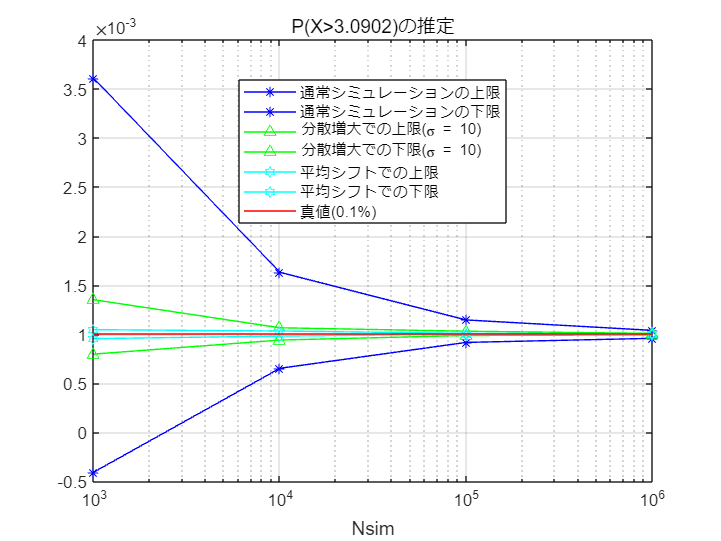

clear;

Nsims = [1000,10000,100000,1000000]';
Nt = 10; 
alpha = 0.01; 

upper1 = zeros(size(Nsims));
upper2 = zeros(size(Nsims));
upper3 = zeros(size(Nsims));
lower1 = zeros(size(Nsims));
lower2 = zeros(size(Nsims));
lower3 = zeros(size(Nsims));

% 分散増大
sig = 10; 
l1 = @(x,sig) sig*exp(-x.^2/2*(1-1/sig^2));

% 平均シフト
tht = 3.0902;
l2 = @(x,tht) exp(-tht.*x+0.5*tht.^2);

for iloop = 1:size(Nsims,1)
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    vs3 = zeros(Nt,1);
    Nsim = Nsims(iloop);
    for jloop = 1:Nt
        rv = randn(Nsim,1);
        % 通常のモンテカルロ・シミュレーション
        rvtmp = rv; 
        tmpv = zeros(Nsim,1) ; 
        tmpv(rvtmp > tht) = 1.0; 
        vs1(jloop) = mean(tmpv); 
        % 分散増大
        rvtmp = sig*rv; 
        tmpv = zeros(Nsim,1);
        tmpv(rvtmp > tht) = 1.0; 
        vs2(jloop) = mean(l1(rvtmp,sig).*tmpv);
        % 平均シフト
        rvtmp = tht + rv; 
        tmpv = zeros(Nsim,1); 
        tmpv(rvtmp > tht) = 1.0;
        vs3(jloop) = mean(l2(rvtmp,tht).*tmpv); 
    end
    rst = estConfidenceInterval(vs1,alpha);
    upper1(iloop) = rst.CIUpper;
    lower1(iloop) = rst.CILower; 

    rst = estConfidenceInterval(vs2,alpha);
    upper2(iloop) = rst.CIUpper; 
    lower2(iloop) = rst.CILower; 

    rst = estConfidenceInterval(vs3,alpha);
    upper3(iloop) = rst.CIUpper; 
    lower3(iloop) = rst.CILower; 
end
nfig = 12; 
figure(nfig);semilogx(Nsims,[upper1,lower1],'b*-');grid; title('P(X>3.0902)の推定'); xlabel('Nsim'); hold on;
semilogx(Nsims,[upper2,lower2],'g^-'); semilogx(Nsims,[upper3,lower3],'ch-'); semilogx(Nsims,0.001*ones(size(Nsims)),'r-'); 
legend('通常シミュレーションの上限','通常シミュレーションの下限','分散増大での上限(\sigma = 10)','分散増大での下限(\sigma = 10)',...
    '平均シフトでの上限','平均シフトでの下限','真値(0.1%)','Location',"best"); hold off;

#### 3-5.Control Variates(制御変数法）

　Control Variateでは、ある確率変数 $M, \mathbb{E}[M] = 0$と実数 $c$を用いて


$$\mathbb{E}\left[ f(X) \right] = \mathbb{E}\left[f(X) +  c M \right]$$


とする。 $M$と $c$は以下の関係を満たすように決めることができれば分散低減を実現できる。


$${\rm Var}\left[ f(X) + c M\right] = {\rm Var}\left[f(X)\right] + c^2{\rm Var}\left[M\right] + 2c {\rm Cov}\left[f(X),M\right] \lt {\rm Var}\left[f(X)\right]$$


左辺の分散を最小にする $c$を $c^*$とすると


$$c^* = - \frac{{\rm Cov}\left[f(X),M \right]}{{\rm Var}[M]}$$


となる。このとき


$${\rm Var}\left[f(X) + c^* M\right] = {\rm Var}\left[f(X)\right] - \frac{\left({\rm Cov}\left[f(X),M\right]\right)^2}{{\rm Var}[M]} = {\rm Var}\left[f(X)\right]\left(1-\rho\left(f(X),M\right)^2\right) < {\rm Var}\left[f(X)\right]$$


となる。 $\rho(f(X),M)$は $f(X)$と $M$の相関係数である。 $f(X)$と $M$の相関が高いと分散低減効果が大きくなることがわかる。

この方法は原理的には相関が０より大きければ分散低減効果が必ず得られる。しかし、実際には $f(X)$の期待値計算をシミュレーションで行うような問題では $c^*$を事前に計算することは困難である。

よって、シミュレーションで推定する $c^*$を $\hat{c}$とすると 


$$\hat{c} = \frac{\sum_{i=1}^N \left(f(X_i) - \bar{f(X)}\right) \left( M_i - \bar{M}\right)}{\sum_{i=1}^{N} \left(M_i-\bar{M}\right)^2}$$



$$\bar{f(X)} = \frac{1}{N} \sum_{i=1}^{N} f(X_i)$$



$$\bar{M} = \frac{1}{N} \sum_{i=1}^N M_i$$


となる。 理論的には、$\hat{c}$の推定と $\mathbb{E}\left[f(X)+\hat{c}M\right]$の推定でのサンプリングが同じ場合には $\hat{c}$の推定誤差と $M$の推定誤差の間に相関があるので$f(X)+\hat{c}M$の推定にバイアスが生じることになるので、独立にサンプリングすることが望ましいことになる。ただし、実際には無視できる水準であることが多い。

適切な $M$を選ぶ方法を一般化することは困難であり、発見的な方法である。デリバティブのように原資産 $X$に対してペイオフが $f(X)$となるような場合では $M = X - \mathbb{E}\left[X\right]$が有力な候補である。

#### 3-6.数値例

$X$が標準正規分布に従うとして$\mathbb{E}\left[\max\left( {\rm e}^{X},1\right)\right]$をモンテカルロ・シミュレーションで評価する。Control Variatesでの $M$を $M = {\rm e}^X - \mathbb{E}\left[{\rm e}^{X} \right] = {\rm e}^X - {\rm e}^{\frac{1}{2}}$とする。

係数 $\hat{c}$の推定は同じ乱数列を使う場合と独立な場合で実験する。解析解が計算できて ${\rm e}^{\frac{1}{2}} N(1) + \frac{1}{2}$となるので、解析解がシミュレーションによる信頼区間に含まれているか確認する。

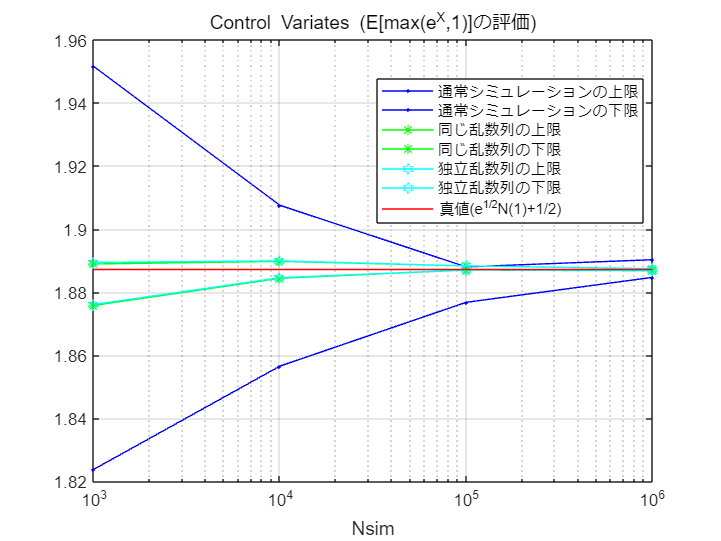

clear;

% 解析解
vana = exp(0.5)*normcdf(1)+0.5; 

% シミュレーション
Nsims = [1000,10000,100000,1000000]';
Nt = 10; 
alpha = 0.01; 

upper1 = zeros(size(Nsims));
upper2 = zeros(size(Nsims));
upper3 = zeros(size(Nsims));
lower1 = zeros(size(Nsims));
lower2 = zeros(size(Nsims));
lower3 = zeros(size(Nsims));

f = @(x) max(exp(x),1); 
m = @(x) exp(x) - exp(0.5); 

for iloop = 1:size(Nsims,1)
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    vs3 = zeros(Nt,1);
    Nsim = Nsims(iloop);
    for jloop = 1:Nt
        rv = randn(Nsim,1); 
        % 通常のモンテカルロ・シミュレーション
        fv = f(rv); 
        vs1(jloop) = mean(fv);
        % Variates Control(同じ乱数列)
        mv = m(rv); 
        tmpv = cov(fv,mv)./var(mv); 
        hatc = -1*tmpv(1,2); 
        vs2(jloop) = mean(fv + hatc*mv);
        % Control Variates(独立な乱数列)
        rv2 = randn(Nsim,1);
        mv2 = m(rv2);
        tmpv = cov(f(rv2),mv2)./var(mv2);
        hatc = -1*tmpv(1,2);
        vs3(jloop) = mean(fv + hatc*mv); 

    end
    rst = estConfidenceInterval(vs1,alpha);
    upper1(iloop) = rst.CIUpper;
    lower1(iloop) = rst.CILower;

    rst = estConfidenceInterval(vs2,alpha);
    upper2(iloop) = rst.CIUpper;
    lower2(iloop) = rst.CILower;

    rst = estConfidenceInterval(vs3,alpha);
    upper3(iloop) = rst.CIUpper;
    lower3(iloop) = rst.CILower;
end
nfig = 13;
figure(nfig);semilogx(Nsims,[upper1,lower1],'b.-');grid; title('Control Variates (E[max(e^X,1)]の評価)'); xlabel('Nsim'); hold on; 
semilogx(Nsims,[upper2,lower2],'*g-'); semilogx(Nsims,[upper3,lower3],'ch-'); semilogx(Nsims,vana*ones(size(Nsims)),'r-'); 
legend('通常シミュレーションの上限','通常シミュレーションの下限','同じ乱数列の上限','同じ乱数列の下限',...
    '独立乱数列の上限','独立乱数列の下限','真値(e^{1/2}N(1)+1/2)','location',"best");hold off;

### ローカル関数

function vf = getMyRNG(a,b,distType)
    %% 乱数生成関数の生成
    arguments
        a (1,1) {mustBeReal} % 定積分の下限
        b (1,1) {mustBeReal,mustBeGreaterThan(b,a)} % 定積分の上限, b > a
        distType (1,1) string {mustBeMember(distType,{'Uniform','TruncatedNormal'})}
    end
    %%
    
    switch distType
        case 'Uniform'
            vf = @(Nx,Ny) (b-a)*rand(Nx,Ny) + a ; 
        case 'TruncatedNormal'
            pd = makedist('Normal');
            pd.mu = (a+b)/2;
            pd.sigma = (b-a)/2; 
            pd = truncate(pd,a,b);
            vf = @(Nx,Ny) random(pd,Nx,Ny);
        otherwise
            error('distType should be Uniform or TruncatedNormal');
    end
end

数値例の補助関数

function rst = exAuxFun1(f,xmin,xmax,Nsim,Nt,alpha)
    %% 定積分計算 演習用関数 一様乱数による評価
    arguments
        f (1,1) function_handle
        xmin (1,1) double {mustBeGreaterThanOrEqual(xmin,0)}
        xmax (1,1) double {mustBeGreaterThan(xmax,xmin)}
        Nsim (1,1) uint32
        Nt (1,1) uint16
        alpha (1,1) double {mustBeGreaterThan(alpha,0),mustBeLessThan(alpha,1)}
    end
    
    % [xmin,xmax]一様分に従う乱数の生成関数
    myrnd = getMyRNG(xmin,xmax,'Uniform');
    
    % シミュレーション
    vs = zeros(Nt,1);
    for iloop = 1:Nt
        xs = myrnd(Nsim,1); 
        vs(iloop) = (xmax-xmin)*mean(f(xs));
    end
    rst = estConfidenceInterval(vs,alpha);
end

function rst = exAuxFun2(lamb,xmin,xmax,Nsim,Nt,alpha)
    %% 定積分計算 切断指数分布に従う乱数による評価
    arguments
        lamb (1,1) double {mustBeGreaterThan(lamb,0)}
        xmin (1,1) double {mustBeGreaterThanOrEqual(xmin,0)}
        xmax (1,1) double {mustBeGreaterThan(xmax,xmin)}
        Nsim (1,1) uint32
        Nt (1,1) uint16
        alpha (1,1) double {mustBeGreaterThan(alpha,0),mustBeLessThan(alpha,1)}        
    end
    
    % 切断指数分布に従う乱数の生成関数
    pd = makedist('Exponential');
    pd.mu = 1.0/lamb;
    pd = truncate(pd,xmin,xmax);
    myrnd = @(Nx,Ny) random(pd,Nx,Ny);
    
    % シミュレーション
    vs = zeros(Nt,1); 
    for iloop = 1:Nt
        xs = myrnd(Nsim,1); 
        vs(iloop) = (1-exp(-lamb*xmax))*mean(xs.^2);
    end
    rst = estConfidenceInterval(vs,alpha);
end

function rst = exAuxFun3(Nsim,Nt,alpha)
    %% 円周率の計算
    arguments
        Nsim (1,1) uint32
        Nt (1,1) uint16
        alpha (1,1) double {mustBeGreaterThan(alpha,0),mustBeLessThan(alpha,1)}
    end
    
    f = @(x) sqrt(1-x.^2);
    vs = zeros(Nt,1);
    for iloop = 1:Nt
        vs(iloop) = 4*mean(f(rand(Nsim,1)));
    end
    rst = estConfidenceInterval(vs,alpha);
end

function [lowers,uppers] = exAuxFun4(myfun,sig,hs,Nsim,Nt,alpha,isReUse,fdmType)
    %% 有限差分による微分計算
    arguments
        myfun (1,1) function_handle
        sig (1,1) double
        hs (:,1) double {mustBePositive}
        Nsim (1,1) uint32
        Nt (1,1) uint16
        alpha (1,1) double {mustBeGreaterThan(alpha,0.0),mustBeLessThan(alpha,1.0)}
        isReUse (1,1) logical {mustBeNumericOrLogical}
        fdmType (1,1) string {mustBeMember(fdmType,{'FD','CD'})}
    end
    vs = zeros(Nt,1);
    lowers = zeros(size(hs));
    uppers = zeros(size(hs));
    
    for iloop = 1:size(hs,1)
        h = hs(iloop);
        for jloop = 1:Nt
            rv1 = randn(Nsim,1);
            if isReUse
                rv2 = rv1; 
            else
                rv2 = randn(Nsim,1); 
            end
            switch fdmType
                case 'FD'
                    v1 = mean(myfun(sig,rv1));
                    v2 = mean(myfun(sig+h,rv2));
                case 'CD'
                    v1 = mean(myfun(sig-0.5*h,rv1));
                    v2 = mean(myfun(sig+0.5*h,rv2));
                otherwise
                    error('unexpected fdmType is used.');
            end
            
            vs(jloop,1) = (v2-v1)/h; 
        end
        rst = estConfidenceInterval(vs,alpha);
        lowers(iloop,1) = rst.CILower;
        uppers(iloop,1) = rst.CIUpper; 
    end
end